# EE 105: First Order Systems in  Simulink

# Name: Buddy Ugwumba SID: 862063029

## Abstract

- The objective of this lab is to familiarize myself with Simulink while exercising systems concepts such as: transfer functions, time constants, pole locations, DC gain, and frequency response.

## 1) First Order Systems

- majority of the lab will focus on the analysis of first-order linear ODE's in SS form. 

- These analysis of these first order systems will be used to demonstrate certain useful concepts that can be generalized to higher order systems. 

- Section 2 summarizes such concepts that will be useful throughout my engineering career

## Section 2 Higher Order Systems:

- d(s) denotes the denominator polynomial of a transfer function H(s). The ploynomial in the denominator of the transfer function is called the **characterisitic ploynomial**.

- The zeros of d(s) are **poles**

$d\left(s\right)$ = 0

- The location of the poles determines the stability properites of the system and greatly effect the transient behavior. 

- For first-order systems of this lab, the pole is at:


$$s=a$$
  

- The time constant of a first-order system is:


$$T=\frac{1}{|a|}$$


- If the real part of all the poles are located in the left half plane (LHP) then the system is **stable** 

- THe DC gain of a stable system with transfer function H(s) is:


$$\mathrm{DC}\;\mathrm{Gain}=\lim_{s\to 0} H\left(s\right)$$


- For a sinusodial input $u\left(t\right)=\mathrm{Acos}\left(\omega t\right)$ to a system with stable transfer function $H\left(s\right)$ as $s\to \infty$


$$y\left(t\right)\to M\left(\omega \right)\mathrm{Acos}\left(\omega t+\Phi \omega \right)$$


where 


$$H\left(j\omega \right)=M\left(\omega \right)e^{j\Phi \left(\omega \right)}$$


- When the amplitude $20\mathrm{log}\left(M\left(\omega \right)\right)$ and the phase shift $\Phi \left(\omega \right)$ are plotted versus $\omega$, the resulting plots are called Bode plots. 

## 1) Cont.

- First order, linear state space modles have the form


$$\begin{array}{l}
\dot{x} \left(t\right)=-\mathrm{ax}\left(t\right)+\mathrm{bu}\left(t\right)\\
y\left(t\right)=\mathrm{cx}\left(t\right)
\end{array}$$


where the signals u(t) and y(t) are the respective input and output and the signal x(t) is the state of the system. 

- The parameters a, b, and c are real constants with numeric values determined by the designer of the system. 

- If the input $u\left(t\right)=0$ for all $t\ge 0$, the general output resonse in the time-domain is known as the **zero input response**:


$$y\left(t\right)=ce^{-\mathrm{at}} x\left(0\right)$$


if $a>0$, then the zero input resonse will converge to 0 as $t\to \infty$. Such a system is **stable**. if $a<0$, then the magnitude of the zero input response will diverge toward infinity as $t\to \infty$. Such a system is **unstable**. The reaminder of this document will focus on the former scenario

- If the initial value of the state is zero i.e. $x\left(0\right)=0$ then the general output response in the time domain is known as the **zero state response**.


$$y\left(t\right)=\int_0^t {\mathrm{ce}}^{-a\left(t-\tau \right)} \mathrm{bu}\left(\tau \right)d\tau$$


## 1.3 First-Order Input Response

- Certain types of inputs are common enogh that they are often used to specify the performacne of systems. These section analyzes the response of the first-order state-space system to some of these common signals

### Zero Input: $u\left(t\right)=0$

- For a stable system, the time constant characterizes the rate of decay of the initial condition. At $t=\tau$, the ouput will ha ve deceased to approximately 37% of its initial value :


$$y\left(\tau \right)={\mathrm{ce}}^{-1} x\left(0\right)\approx 0\ldotp 37y\left(0\right)$$


- When the designer has data corresponding to a first-order system, the above formula provides one method for estimating the time constant (i.e., estimating the parameter a) by simply finding the value of time at which $y\left(t\right)=0\ldotp 37y\left(0\right)$

- A second method for estimating the value of the time constant is to use the slope of y(t) at t = 0. The line tangent to the graph of y(t) at t = 0 is


$$v\left(t\right)=y\left(0\right)-\mathrm{ay}\left(0\right)t$$


- This line inersects the t-0axis at $t=\frac{1}{|a|}=\tau$. To use the second method, draw a line on the plot of the y(t) data that is tangent to y(t) at t = 0 and measuer the time t which the line intersects the t-axis. 

### 1.3.2 Step Input $u\left(t\right)=\mathrm{A1}\left(t\right)$

- The Laplace tranform of the step function is:


$$U\left(s\right)=\frac{A}{s}$$


- The DC Gain of a stable system is the ratio of the magnitude of the steady state output to the magnitude of the applied step input

- For first-order stable linear systems, steady state is often considered to apply for any $t\ge 4\tau$, since $e^{-4} <2%$

- The DC gain $\frac{\mathrm{cb}}{a}$

### 1.3.3 Sinusoidal Input: $u\left(t\right)=\mathrm{Acos}\left(\omega t\right)$for $t\ge 0$ 

- $\omega$ is in radians

- The time domain equivalent is:


$$y\left(t\right)\approx \frac{\mathrm{cb}}{\sqrt{\omega^2 +a^2 }}\mathrm{cos}\left(\omega t+\mathrm{atan2}\left(-\omega ,a\right)\right)$$


## 3 Prelab

2. The figures below plot the zero input ( i.e., u(t) = 0). time-response of various different systems . For each:

(a) State whehter or not the responce could correspond to a first order linear system

Recalll that a zero input time response is:


$$y\left(t\right)=ce^{-\textrm{at}} x\left(0\right)$$


Thus, the responses that could correspond to a first order linear system are figures (a), (c), and (f).

(b) The reason why the remaining graphs do not correspond to a first order linear system is because no value of t would produce a general out response of their shope. SPecifically, (e) is linear, (d) is sinusodial input, and (b) has a shar discontinuitiy. 

(c) The sign of the paramater a for (a) is negative. I know this because the zero input response converges at zero. I also know that a > 0.  I estimate the $|a|\approx 4$The sign of the parameter a for figure (c) is positive because the response diverges. The value of the time constant is 0 because the system is unstable since it diverges towards infinity as $t\to \infty$.The parameter has no sign in figure (f) and its value is 0. The value of the time constant is undefined; it does not exist because the a is on the axis and not strickly on the left hand plane. 

3. 

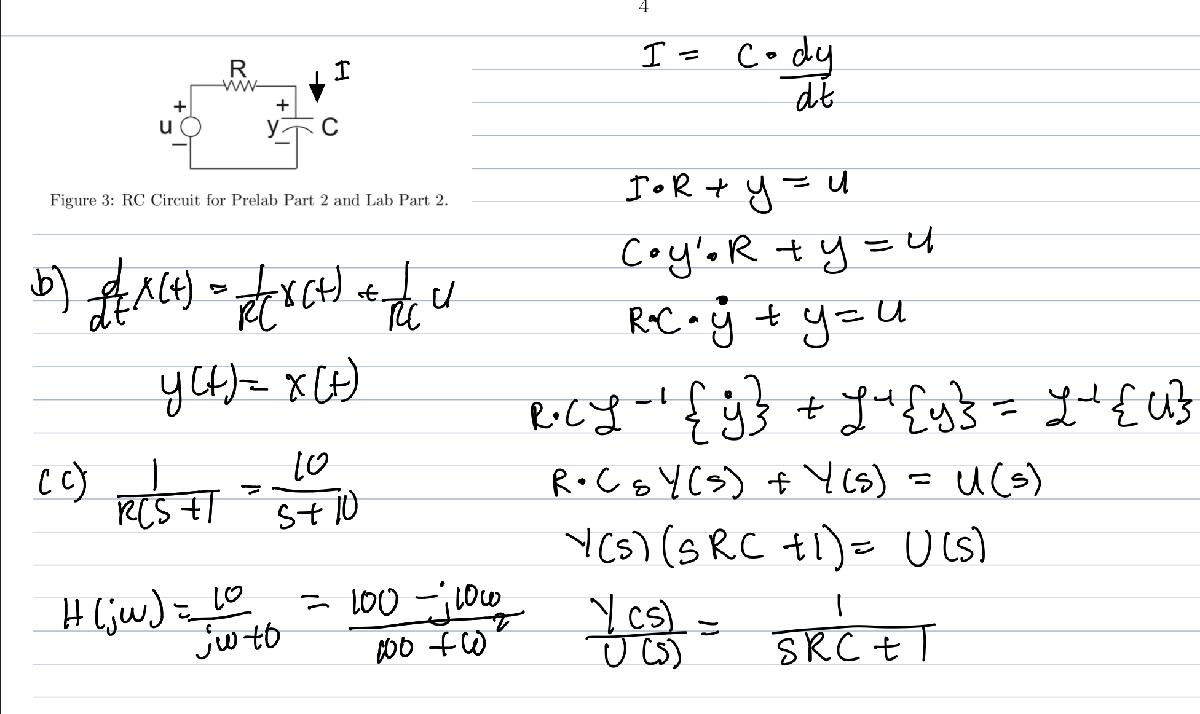

w = [0,0.01,0.1,1,10,100]

w =          0    0.0100    0.1000    1.0000   10.0000  100.0000


clear i;
H = (100 - 1i*10.*w)./(100 + w.^2);
% Magnitude
abs(H)

ans =     1.0000    1.0000    1.0000    0.9950    0.7071    0.0995


% Phase
rad2deg(angle(H)) % Unit: degree

ans =          0   -0.0573   -0.5729   -5.7106  -45.0000  -84.2894


H = tf(10,[1 10])


H =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



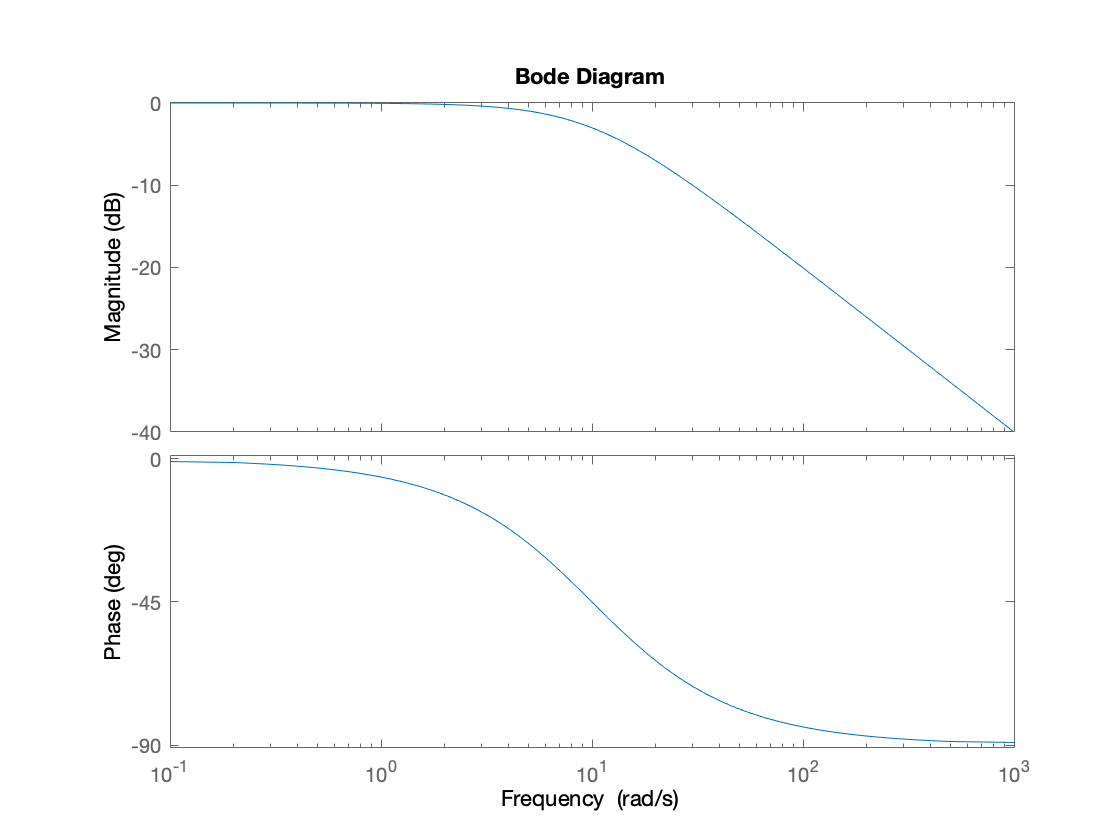

bode(H)

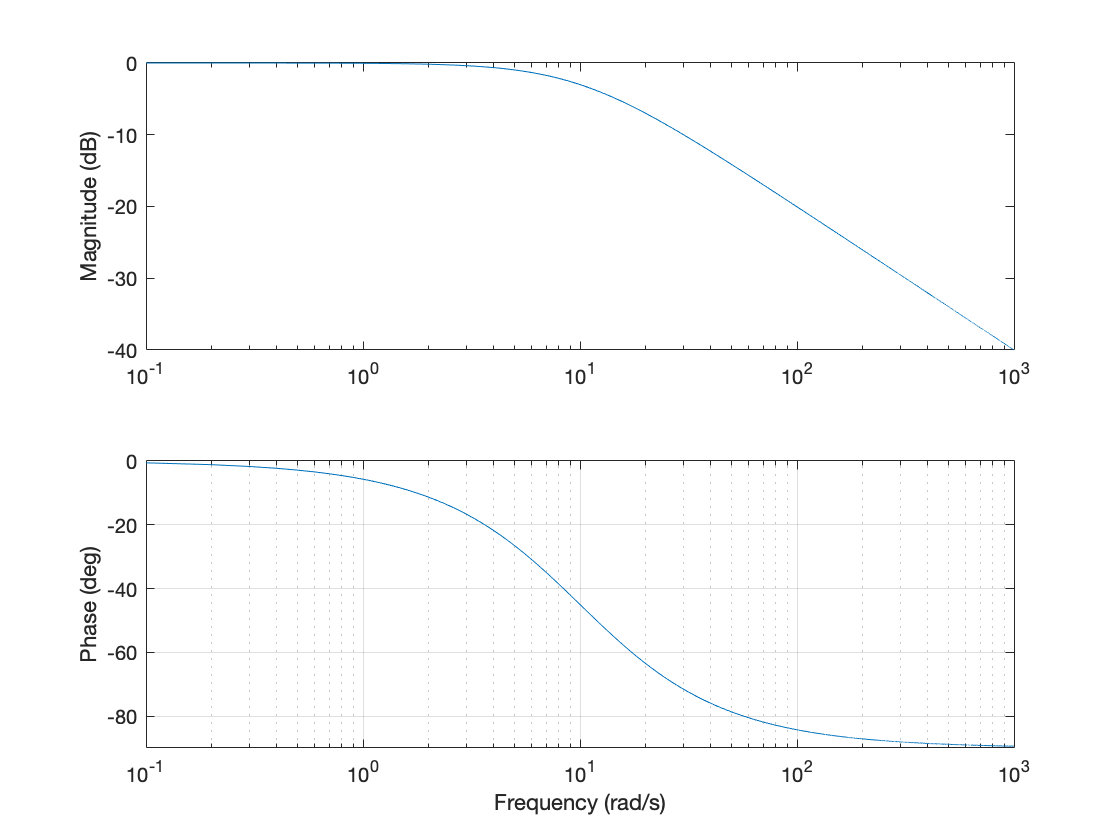

%For proving (c)
w = 0.1:0.1:1000;
H = (100 - i*10.*w)./(100 + w.^2);
% Compute magnitude using eqn.(11)
M = abs(H);
% Compute phase using eqn.(11)
Phi = rad2deg(angle(H));
figure
subplot(211)
% Semilogx to uniformize the x-axis to the results in 'bode'
% log10 to compute the DB of M(s)
semilogx(w,20*log10(M));
ylabel('Magnitude (dB)')
xlim([0.1,1000])
ylim([-40,0])
subplot(212)
semilogx(w,Phi);
ylim([-90,0])
grid on
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')

# 4.1 Part 1 – Time Constant Estimation (20'')

1. (10'')

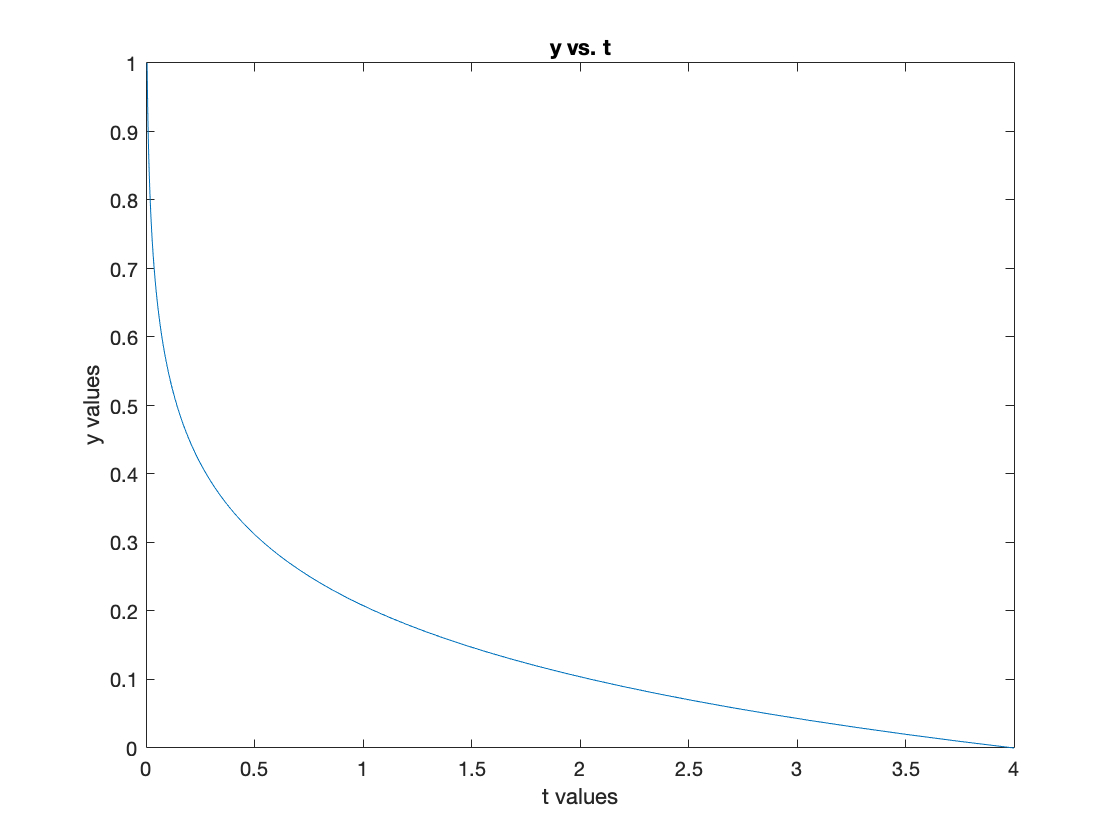

% load data
load('EE105_Lab3data.mat');
% Plot y versus t. Make sure that the figure is properly
% labeled as indicated in Lab 1.
figure 
plot(y,t)
ylabel('y values')
xlabel('t values')
title('y vs. t')

2. (5'' for each method, total 10'')

Estimating the time constant have to be done by MATLAB code. No points will be given by manully computation.

Method 1:

y($\tau$) = 0.37y(0)

y_tau = 0.37*4.00

y_tau = 1.4800

% Find the value for y_tau. Note that the index of a vector in MATLAB start
% at 1.
% You get the y(tau), but how to find tau?
% Search 'find' in MATLAB documentation, read the statemetent.
% For example,
h = t;
x = y_tau;
% If I want to find where is 11 in array h, I can use
% What if x = -11.1, find the closest position in 'h'?
% Directly use find(h == x) will cause empty output.
% You can find the minimum of abs(h - x). (Try MATLAB function 'min')
% Once you get the index 'ind' in vector y.
% Then tau = t_out(ind);
index = find(abs(y-x)==(min(abs(y-x))))

index = 16

y(index)

ans = 1.4715

t(index)

ans = 0.1500

Method 2:

Compute a. a = - dydt(0)/y(0).

Use y(t(1)) and y(t(2)) to compute the slope dydt(0) at t = 0.

Then compute $\tau$.

Method_2 = (((y(1) - y(2))/(t(1) -t(2)))/y(1))*-1

Method_2 = 6.4493

tau = 1/Method_2

tau = 0.1551

# 4.2 Part 2 – Simulation (70'')

**You report should show the simulink model, the output and input by taking screenshot and inserting to your report.**

**For the output and input figure, you should state which curve is the input and which curve is the output.**

**Submit three simulink files to MATLAB Drive.**

Output and input (for initial condition of the integrator to 1.0): (3'')  

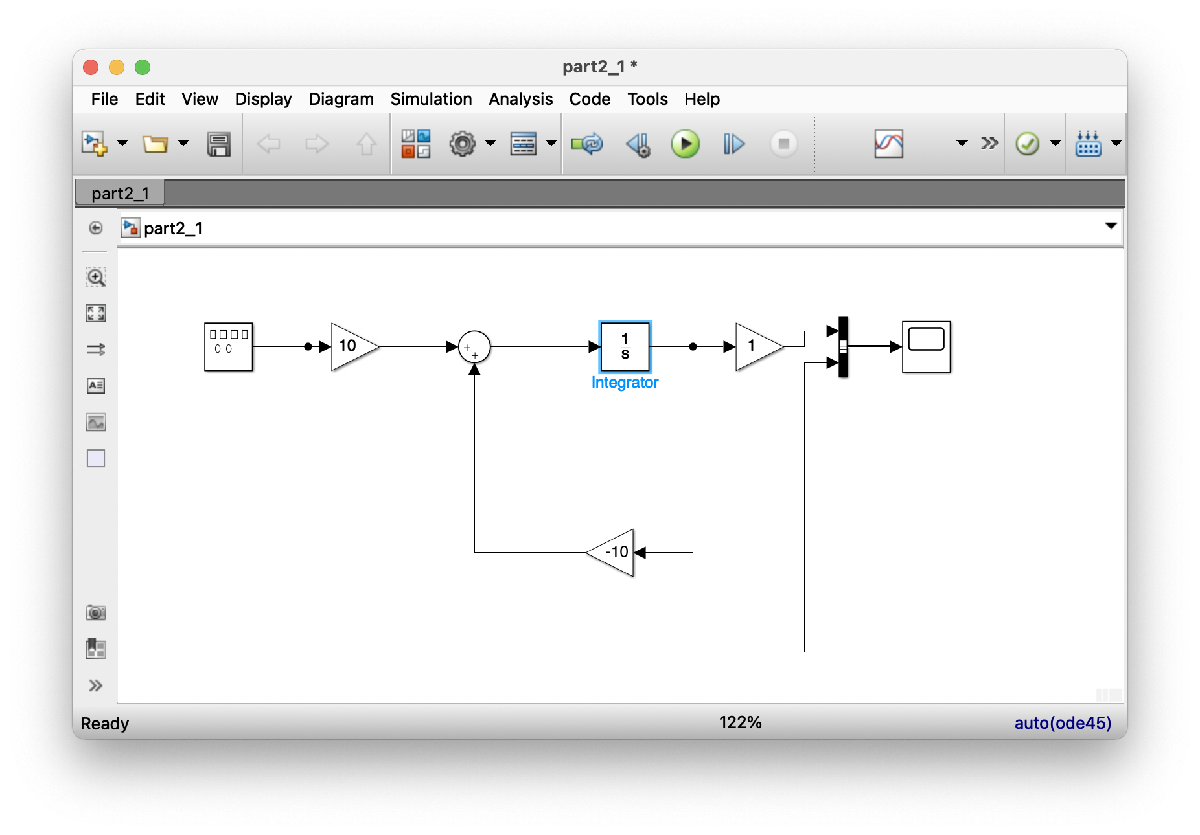

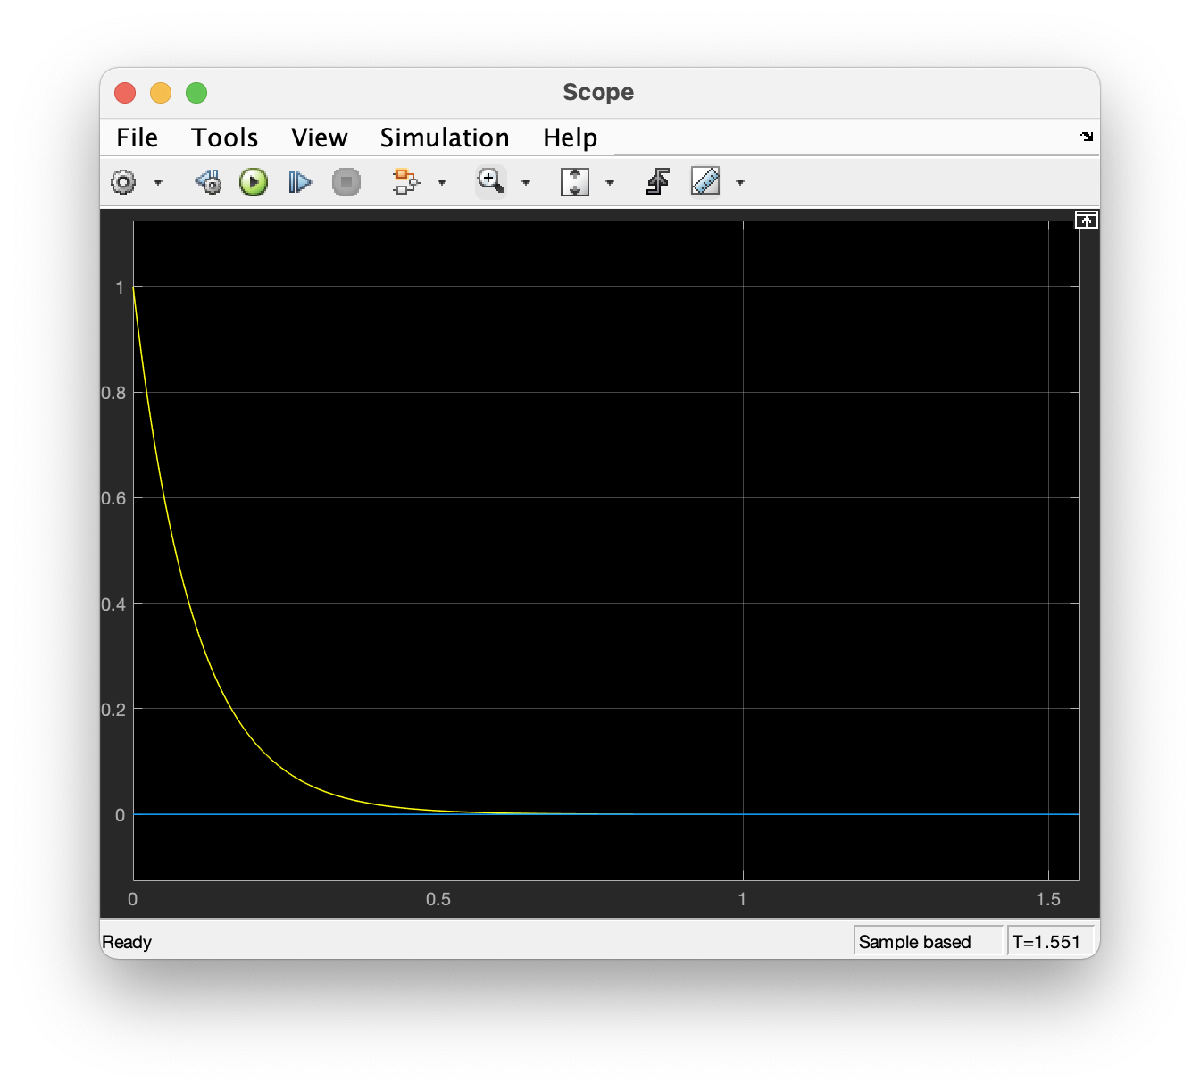

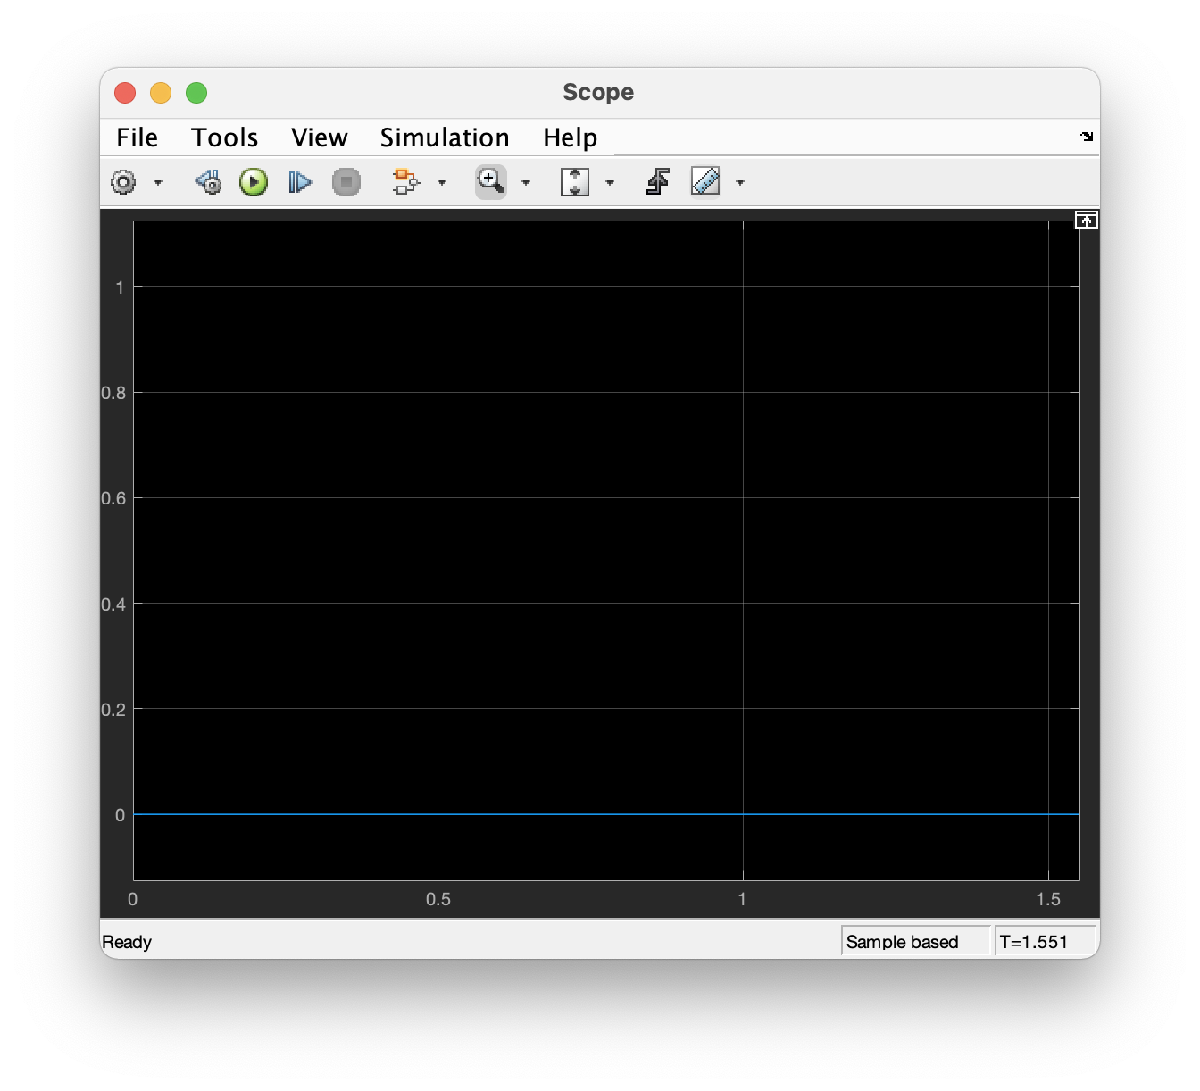

Output and input (for initial condition of the integrator to 0.0): (2'')  

2.  (Name the simulink file as 'part2_2')

The model: (5'')

Output and input: (10'') 

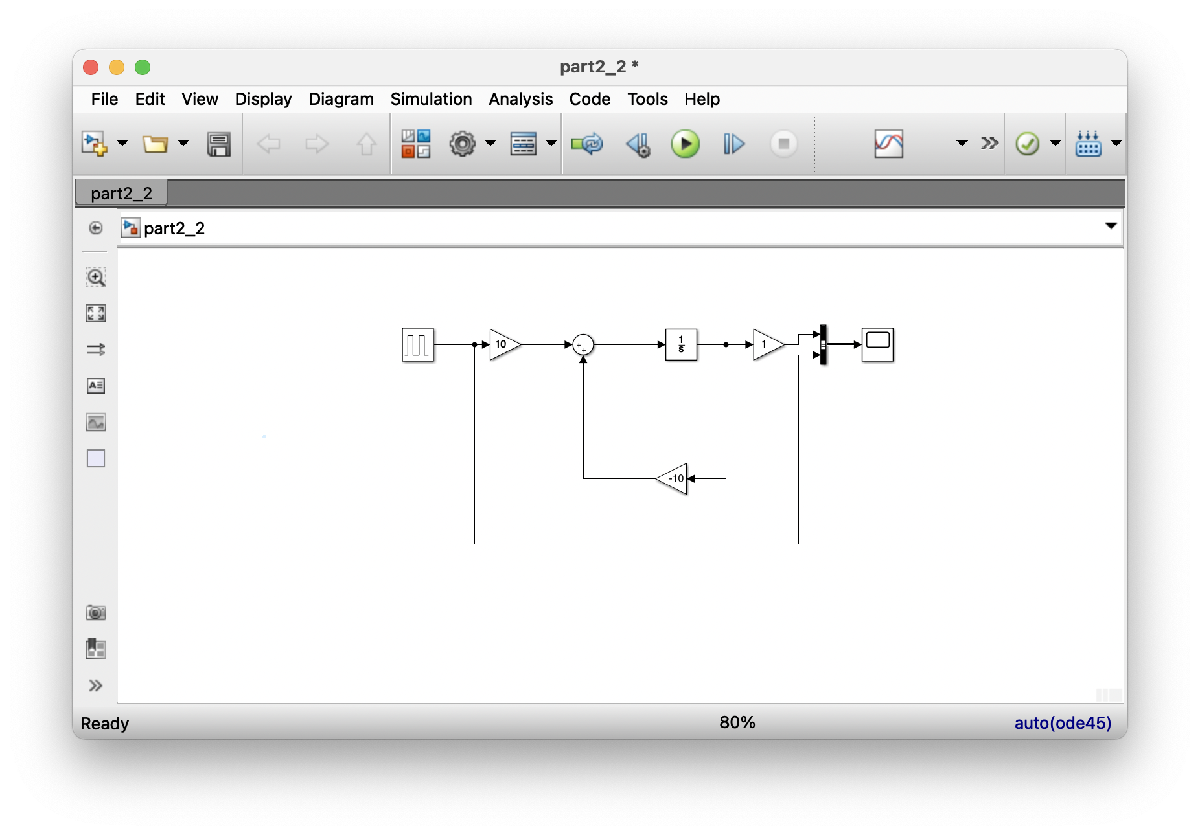

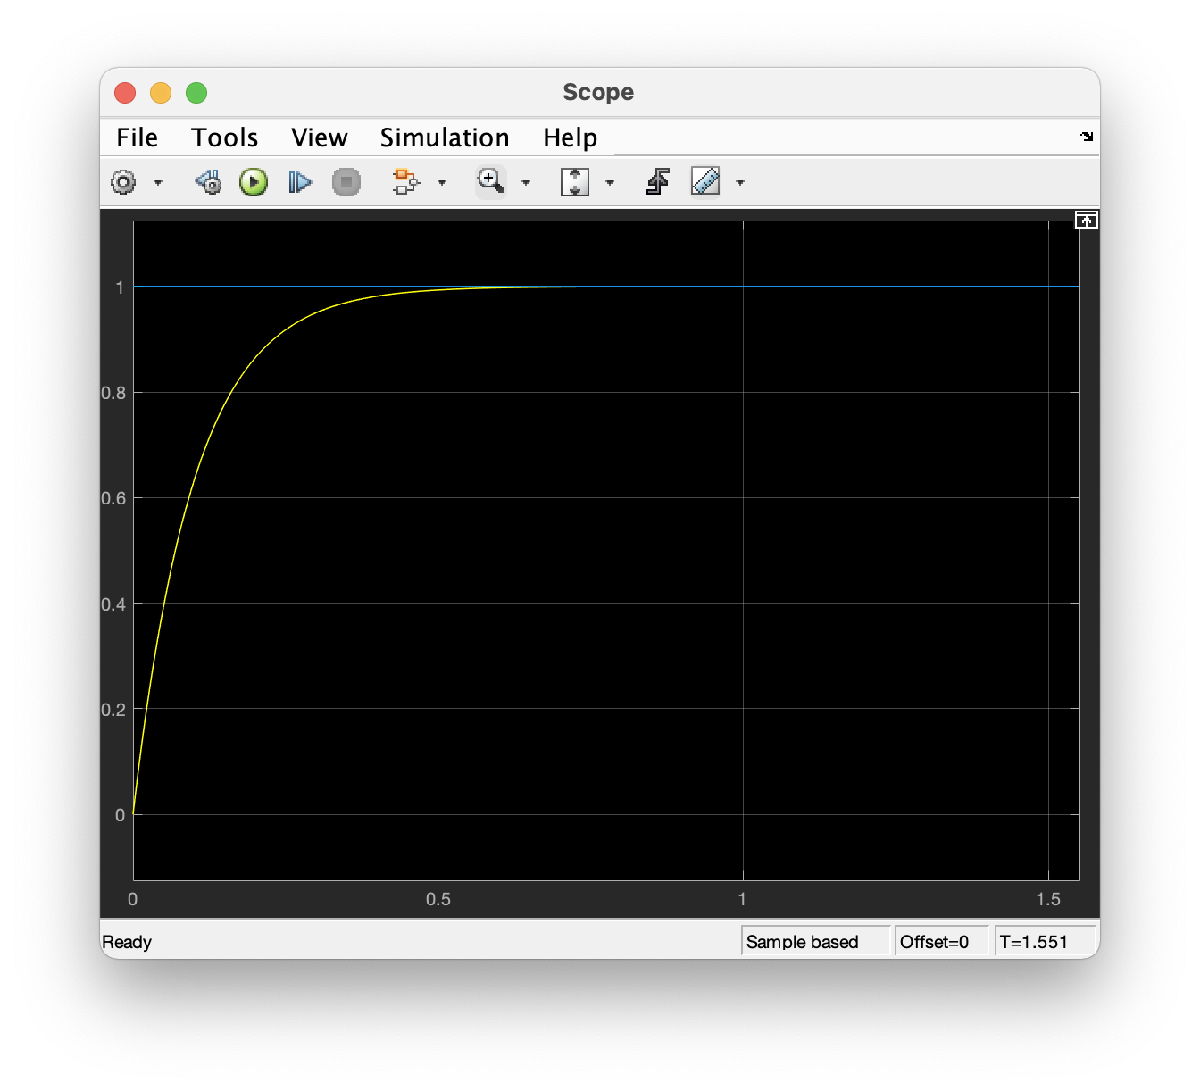

2.(c) How long does the response take to get to steady state?  (5'')

 Show the '**cursor measurement**' and answering this question.

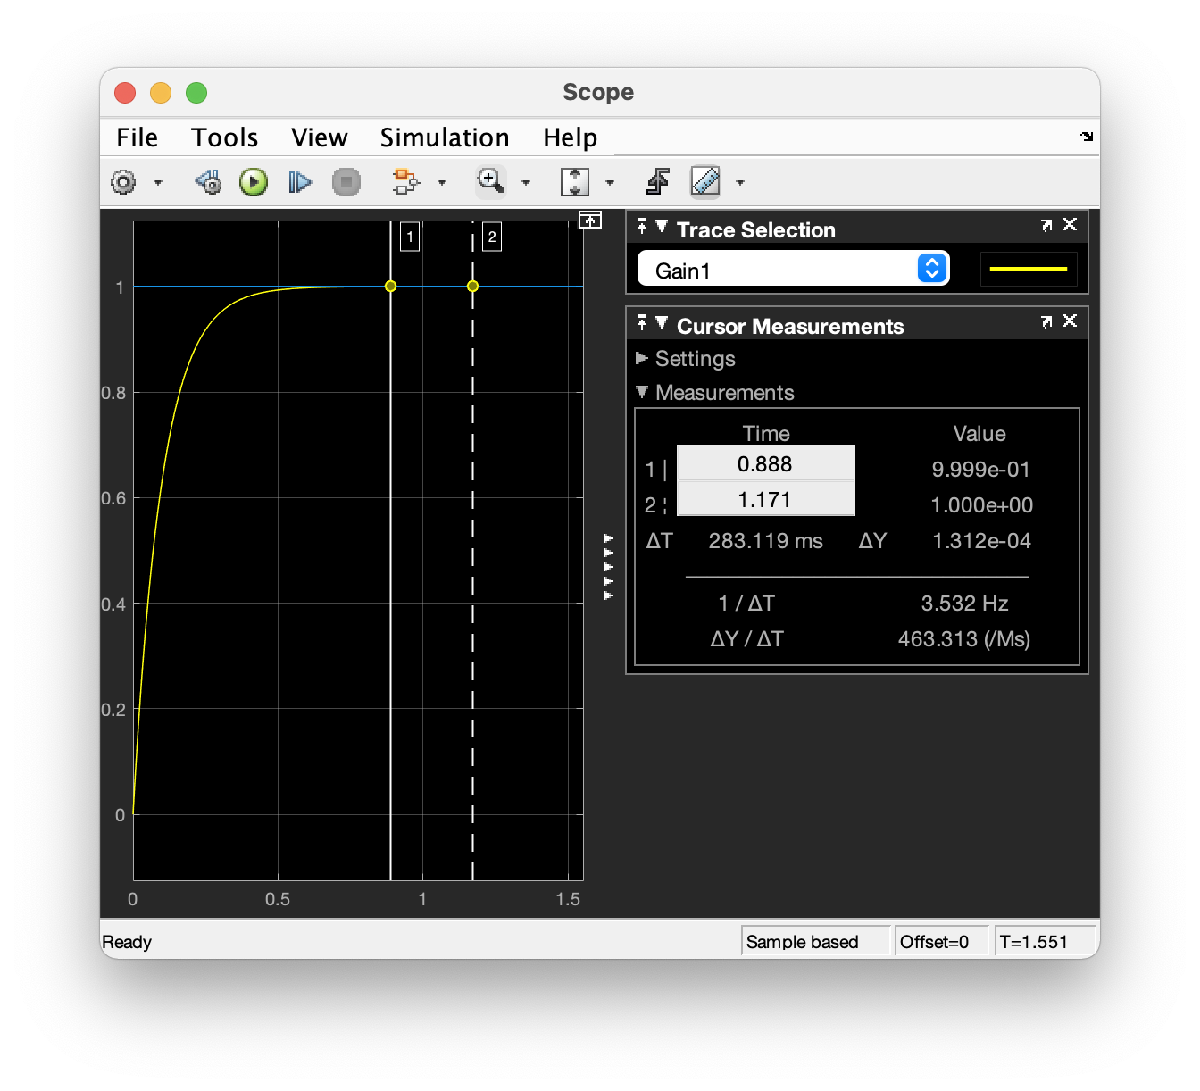

 How does this compare with the time constant?   (5'')

It took me 0.88ms to reach steady state. The time constant from our period was close to the calculated vaue

2.(d)  (5'')

Since the steady state yalue of y is one, it matches with the predicated value caluculated from the dc analysis

3. (Name the simulink file as 'part2_3') 

In your report, you just need to show the simulation result for $\omega =1\ldotp 00\ldotp$

The model: (5'')

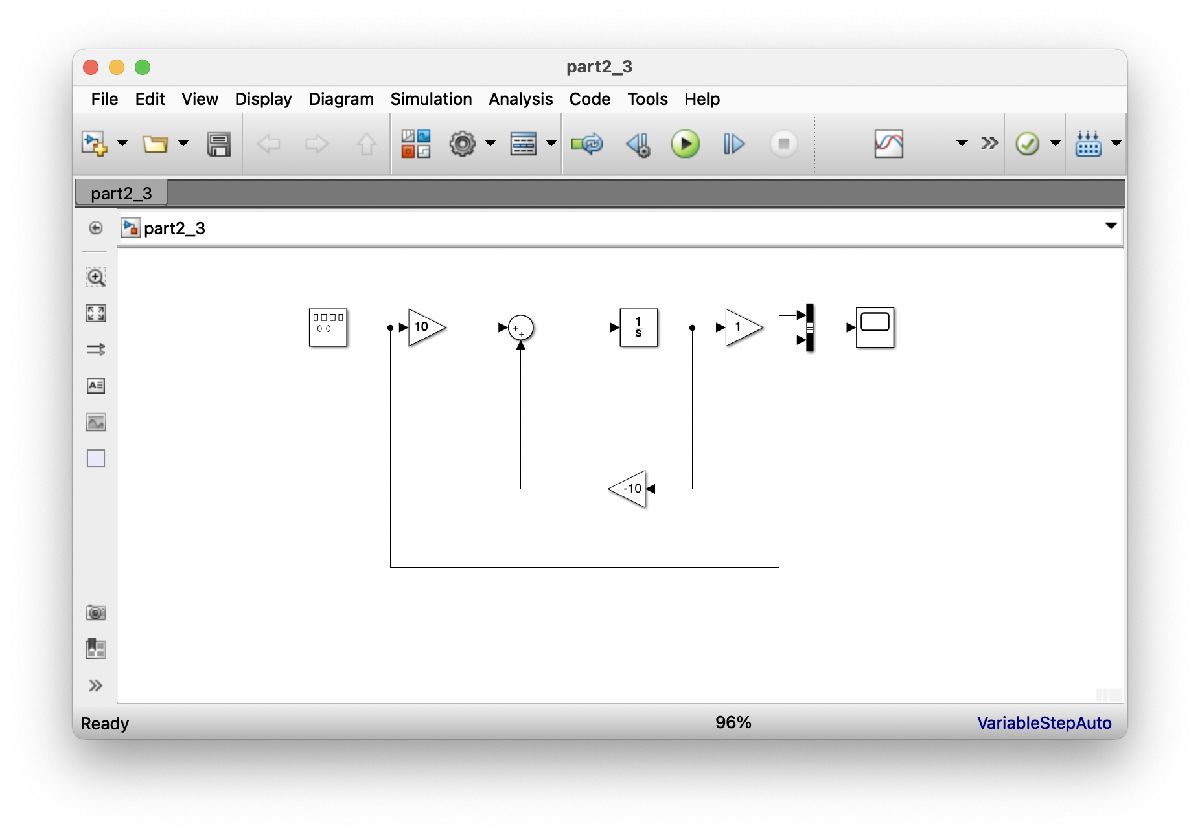

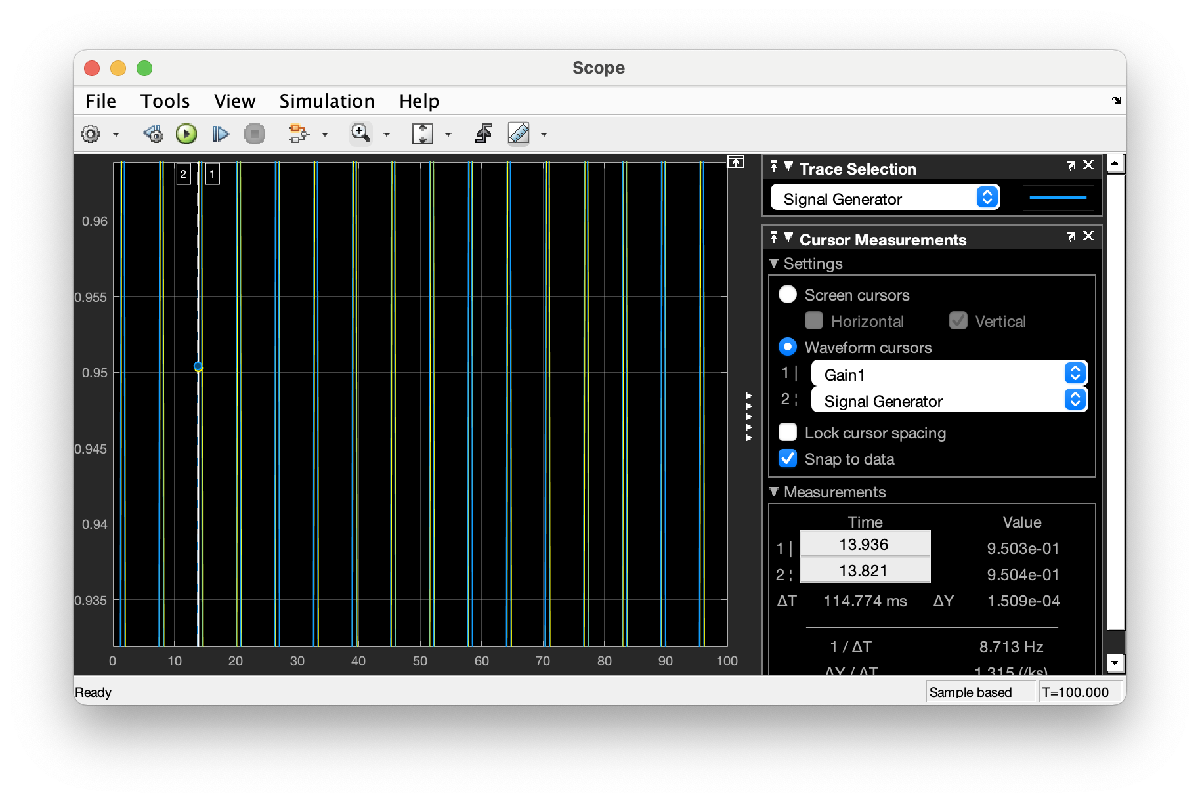

3.(e) Does the magnitude of your output = 0.995? (5'') 

Measure the phase between y and u in the simulation results. Show the '**cursor measurement**'. Measure the phase shift. Note that the axis in the 'scope' is time 't'. You shoud convert the '$\Delta T$' to degree. Does the phase shift you measured approximatelly equal to -5.7106 degree? (10'')

It was not close to approximate value mine was 6.6682. My closefr measuer was close the output, but not the exact measure as well.

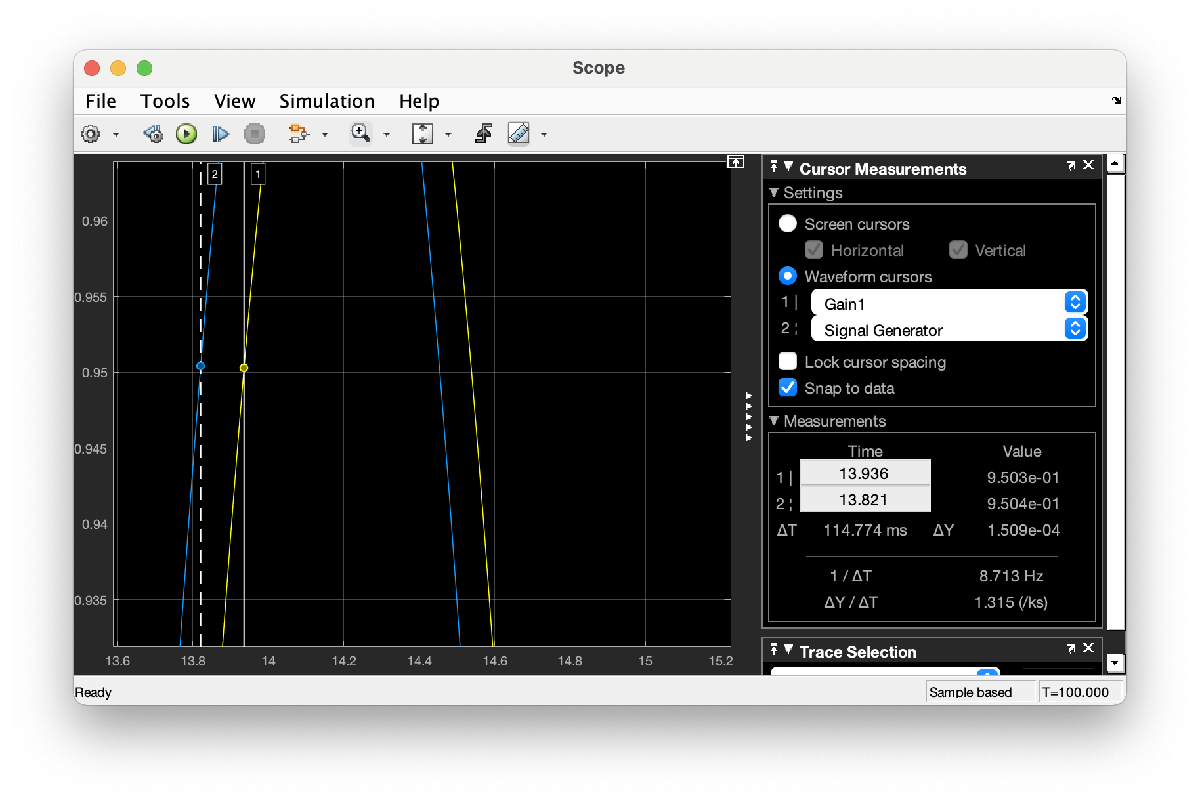

3.(e) Does the magnitude of your output = 0.995? (5'') 

Measure the phase between y and u in the simulation results. Show the '**cursor measurement**'. Measure the phase shift. Note that the axis in the 'scope' is time 't'. You shoud convert the '$\Delta T$' to degree. Does the phase shift you measured approximatelly equal to -5.7106 degree? (10'')